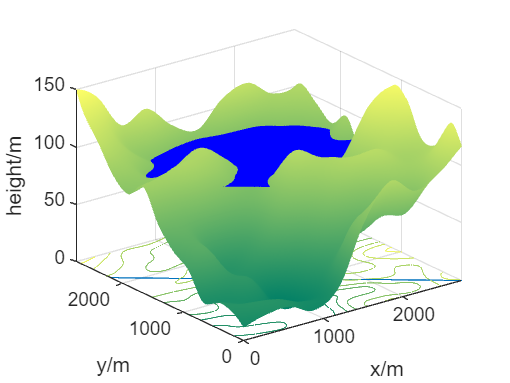

water_surface = reservoir_image(80);

function water_surface = reservoir_image(water_level)
% code here
load("project1_data.mat");

% the dam defined by the equation
dam = 2200 - 0.8 * x;

% this graphs the valley
surfc(x,y,valley,'edgecolor','none');
xlabel("x/m")
ylabel("y/m")
zlabel("height/m")
hold on

% this initializes the water surface to be all at the water level
water_surface = water_level .* ones(length(valley)); % this is the entire surface of water untouched
% restrictions on each of the elements
for i = 1:length(x)
    for j = 1:length(y)
        % water is below the dam line or water belongs (is inside) to the reservoir
        if y(i) < dam(j)  || water_surface(i,j) < valley(i,j)
            water_surface(i,j) = NaN;
        end
    end
end

% this graphs the water
surf(x,y,water_surface,'edgecolor','none','facecolor','b');
colormap summer

plot(x,dam);

saveas(gcf,'reservoir_image.jpg');
end